[d,time] = loadPclampData([fn '19128028.abf']);

opening M:\Babola Data\190128\19128028.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


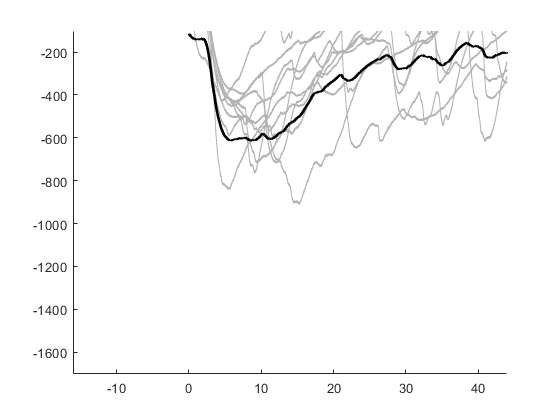

figure; hold on;
count =1;
for i=[1:10]
    plot(time,d(:,:,i)-mean(d(1:5000,:,i),1),'Color',[0.7 0.7 0.7],'LineWidth',0.1);
    count = count + 1;
end
plot(time, mean(d(:,:,1:10),3),'Color','k','LineWidth',2)



h = figure;2

ans = 2

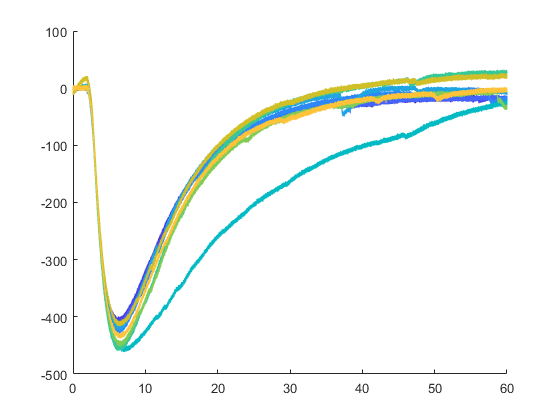

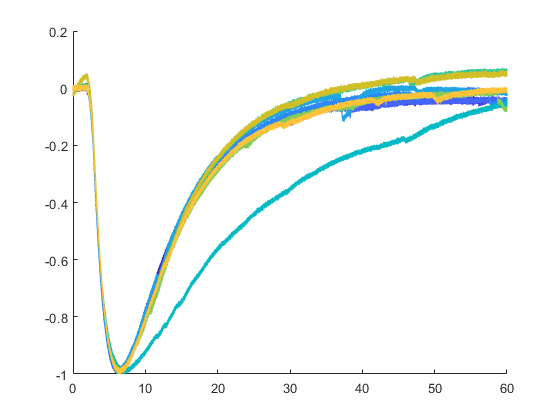

hold on;
h1 = figure;
hold on;
set = [15:24];
step = round(64/size(set,2));
count = 1; cmap = parula;
for i=set
    figure(h);
    plot(time,d(:,:,i)-mean(d(1:5000,:,i),1),'Color',cmap((count-1)*step+1,:),'LineWidth',0.1);
    
    norm = d(:,:,i)-mean(d(1:5000,:,i),1);
    norm = norm / -min(norm);
    figure(h1);
    plot(time,norm,'Color',cmap((count-1)*step+1,:),'LineWidth',0.1)
    count = count + 1;
end

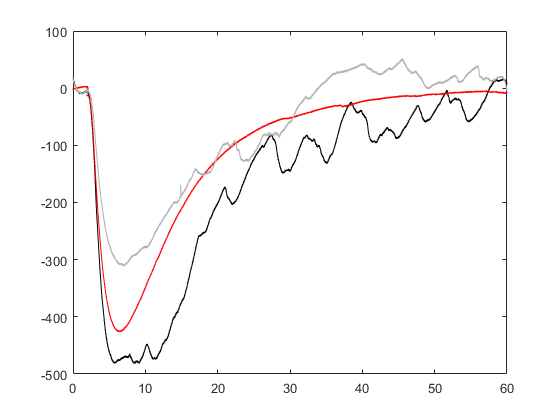

figure;
baseline = mean(d(:,:,1:10),3);
MRS = mean(d(:,:,14:24),3);
washout = mean(d(:,:,35:40),3);
plot(time,baseline-mean(baseline(1:5000)),'Color','k');
hold on;
plot(time,MRS-mean(MRS(1:5000)),'Color','r');
plot(time,washout-mean(washout(1:5000)),'Color',[0.7 0.7 0.7]);

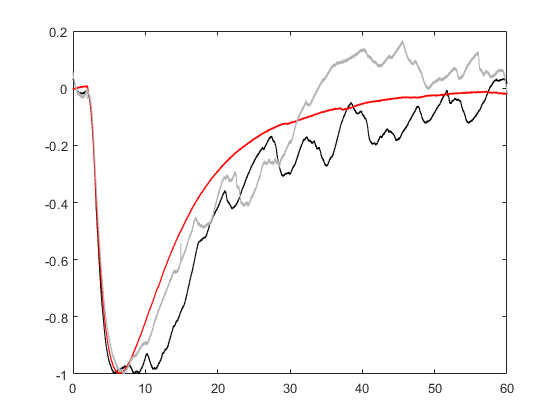


%%normalized
figure;
baseline = baseline - mean(baseline(1:5000));
baseline = baseline / -min(baseline);
MRS = MRS - mean(MRS(1:5000));
MRS = MRS / -min(MRS);
washout = washout -mean(washout(1:5000));
washout = washout / -min(washout);
plot(time,baseline,'Color','k');
hold on;
plot(time,MRS,'Color','r');
plot(time,washout,'Color',[0.7 0.7 0.7]);